# Project 1 3M

Bill Fan + Elvis Wolcott

## Question

How can the societal impacts of public health interventions be limited while keeping a pandemic within hospital capacity?

Our question is a design question because it attempts to answer how policy makers can craft an intervention that balances multiple concerns. In an ideal world, the only consideration of public health interventions would be reducing the number of cases during an outbreak. In practice, policy makers have to consider the cost of implementation and the economic impact of each intervention. Asking this question will allow us to explore how different elements of a response such as speed of implementation and forecasting distance affect the ability to adequately respond to the virus.

## Model

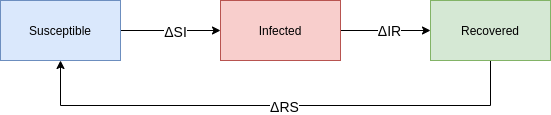

### SIR+ Model Equations


$$\Delta I_t = \beta \times I_t \times S_t \times (1 - \lambda u)\\
\Delta R_t = \gamma \times I_t \\
\Delta S_t = \alpha \times R_t \\
S_{t+1} = S_t - \Delta I_t + \Delta S_t\\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t - \Delta S_t\\$$



$$\frac{dS}{dt} = -\beta \times I_t \times S_t + \alpha \times R\\
\frac{dI}{dt} = \beta \times I_t \times S_t \times (1 - \lambda u) - \gamma \times I_t \\
\frac{dR}{dt} = \gamma \times I_t - \alpha \times R_t \\$$


### Model with Re-Infection

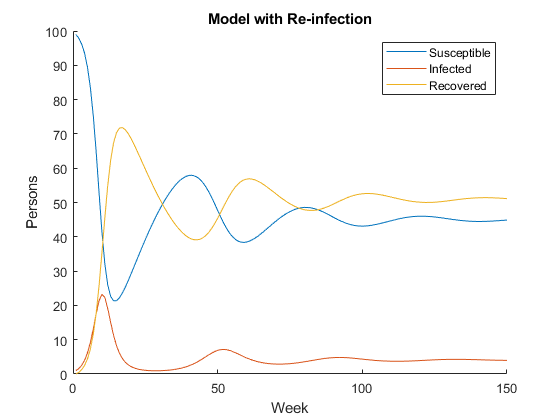

% Initialization
weeks = 150;

s_0 = 99;
i_0 = 1;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
% lambda and control are 0 to show base model
lambda = 0;
control = 0;

% Run simulation
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("Model with Re-infection")

For this project we have created two models: A disease model, and a controller model.

To create the disease model, we added a new term $\left(1-\lambda u\right)$ to factor in the effects of an external control on the spread of the disease. This essentially scales $\beta$ by our external control, and thus changing the rate of infection. Within the term $\left(1-\lambda u\right)$, $u$ is the amount an external control is used, from 0 to 1 (eg. percent population social distancing), and $\lambda$ is the effectiveness of said external control from 0 to 1 (eg. Say if everyone wore masks, the rate of infection would only be 20% of what it originally was, so $\lambda =0\ldotp 2$). The product of $\lambda$ and $u$ is then subtracted from 1 because the effects of both terms inversely correlate with the change in rate. When everyone is social distancing, or when social distancing is 100% effective, then the new effective $\beta$ is 0. Conversely, when nobody is social distancing, or if it has no effect on the spread of the disease, then the effective $\beta$ is not affected.

Our controller uses an incredibly simplified version of constant value model predictive control (MPC), using our SIR model for its predictions. At every time step in the world simulation, the controller takes the current $S$, $I$, and $R\;$stock counts, as well as the $\beta$, $\gamma$, and $\lambda$ values, and simulates the pandemic for all possible control values between 0 and 1 within a given horizon/timeframe/window. After it sweeps through all control values, it examines the local maxima values of each simulation’s infected curve, and chooses the highest one that is under a certain threshold (acceptable case count). This control value is then applied to the real world simulation. A control lag can also be added to the simulation, so that the control values are applied weeks after they have been generated, to simulate how it takes time for the latest pandemic best-practices to be adopted by the public.

To build the disease model, we had to make the enormous abstraction that disease controls such as social distancing could be simplified down to two terms: effectiveness and percent adoption. By modeling the effects of the controls as simply scaling $\beta$, we also assumed that these terms would have a linear and constant effect on the overall infection rate of the disease. While these are enormous abstractions, they helped us create a simple model of the effects of controls on a pandemic that still gives us some insight into how a pandemic should best be controlled, and what it is like being a policy maker.

In terms of model fitting, we got our $\beta$, $\gamma$, and $\alpha$ by fitting the data to the given influenza data, and tuning for a second-wave period of roughly 50 weeks. $\lambda$ is a parameter that can then be changed to adjust for the effectiveness of the preventative measure that you are trying to simulate. For example, to simulate a lockdown, $\lambda$ would be 1, since if everyone is in lockdown it would have a 100% effectiveness of stopping disease spread. Simulating everyone wearing masks would be 0.75, since the effectiveness of that is 75% (see here [https://aatishb.com/maskmath/)](https://aatishb.com/maskmath/))

TODO: update (we fixed it)

For the threshold and horizon length, we have left these as parameters for examining how the simple controller performs in various scenarios. Unfortunately, a realistic threshold number cannot be used with the simulation, as the simulation breaks when numbers become too big or small, possibly due to floating point error in MATLAB. For a realistic threshold, according to ([https://covid19.healthdata.org/united-states-of-america/massachusetts?view=resource-use&tab=trend&resource=all_resources](https://covid19.healthdata.org/united-states-of-america/massachusetts?view=resource-use&tab=trend&resource=all_resources)) there are ~5000 hospital beds in the state of Massachusetts. The population of Massachusetts is 6.5 million ([https://www.census.gov/quickfacts/MA](https://www.census.gov/quickfacts/MA)), which leaves the percentage population threshold to be $5000/6500000=0\ldotp 00077$, and the simulation stops working when the thresholds are that small due to problems that we will see later. It only really works for values above 0.5%. What does a threshold of 0.5% of population mean? It means that at best this model can only keep cases below 0.5% of the population. Covid has a lethality rate of 10%. Thus, for Covid, $300,000,000*0\ldotp 005*0\ldotp 1=150,000$ deaths, which isn’t much better than what we are at right now! Thus, to realistically use this model to simulate and control pandemics the math will need to be corrected for it to be able to control for much smaller thresholds.

### Verification

Our model should:

- Have a constant total population

- A $\lambda$ of $0$ should **NOT** result in results different from the base model

- A $\lambda$ of $0$ should **NOT **respond to changes to $u$

- An $\alpha$ of $0$ should **NOT **exhibit a second wave

- A $\gamma$ of $0$ should **NOT** show recovery

- A $\beta$ of  $0$ should **NOT **show new infections

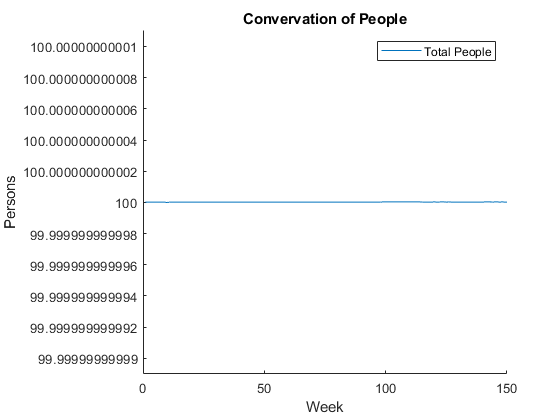

% test: total population is constant
figure(2); clf; hold on;
lambda = 0.75;
threshold = 10;
horizon = 10;
delay = 2;
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S + I + R);
label1 = "Total People";
legend({label1});
xlabel("Week")
ylabel("Persons")
title("Convervation of People");

% there's a bit of floating point error - let's see how much
var(S + I + R)

ans = 1.9111e-28

eps(0.5) % according to the docs this should give us a good idea what the error to expect is

ans = 1.1102e-16

There is a slight variance in the total people from week to week, which may be due to floating point rounding errors. Comparing this value to the expected range of floating point error confirms it can reasonably be attributed to floating point error. To the degree possible with floating point operations, the model seems to conserve people. The observed error falls within the range of $1*{10}^{-24}$ to $1*{10}^{-28}$. To put this into perspective, there's about 30 trillion cells in the human body and 10 billion which works out to $3*{10}^{23}$ human cells on earth.

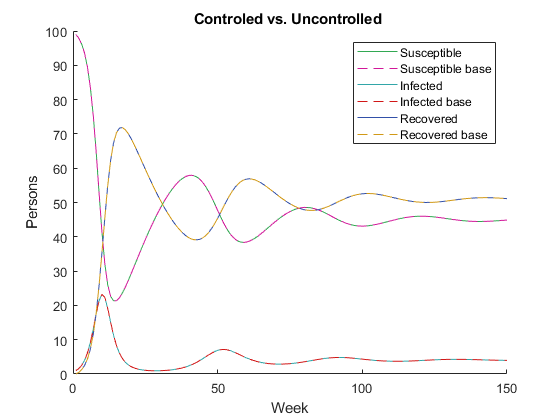

% test: lambda of 0 - same as base model
figure(3); clf; hold on;
lambda = 0;
threshold = 10;
horizon = 10;
delay = 2;
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

xlabel("Week")
ylabel("Persons")

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base});
title("Controled vs. Uncontrolled ");

As expected, a lambda of 0 (indicating an ineffective control) results in a response identical to the base model.

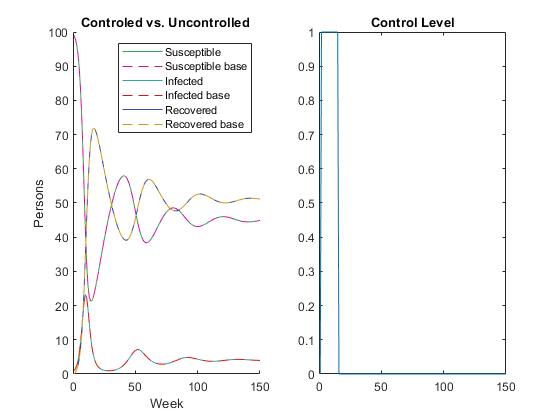

% test: lambda of 0 - doesn't respond to controller
figure(4); clf; hold on;
subplot(1,2,1); hold on;
lambda = 0;
threshold = 10;
horizon = 10;
delay = 2;
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

xlabel("Week")
ylabel("Persons")

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base});
title("Controled vs. Uncontrolled ");
subplot(1,2,2)
plot(W, U); labelU = "Control";
title("Control Level");

Although a non-zero control value was applied, the controlled model did not deviate from the base model as was expected.

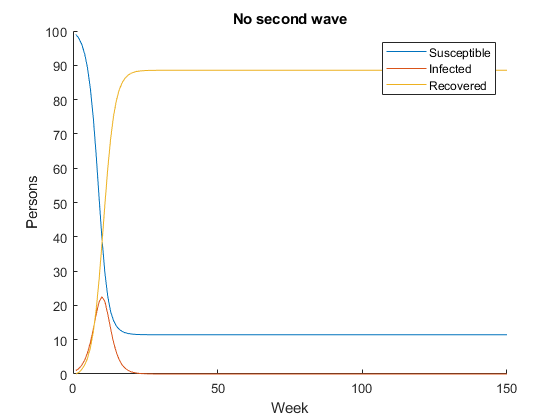

% test: alpha of 0 - shouldn't have a second wave
alpha = 0;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(5); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No second wave")

As expected, there is no re-infection.

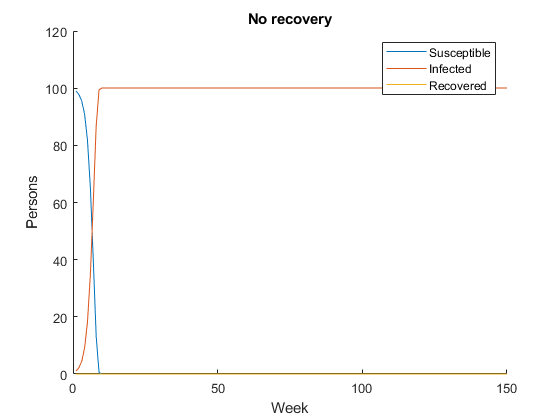

% test: gamma of 0 - shouldn't have recovery
alpha = 0.05;
gamma = 0;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(6); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No recovery")

As expected, the infections reach 100 because there is no recovery.

% test: beta of 0 - shouldn't have new infections
beta = 0

beta = 0

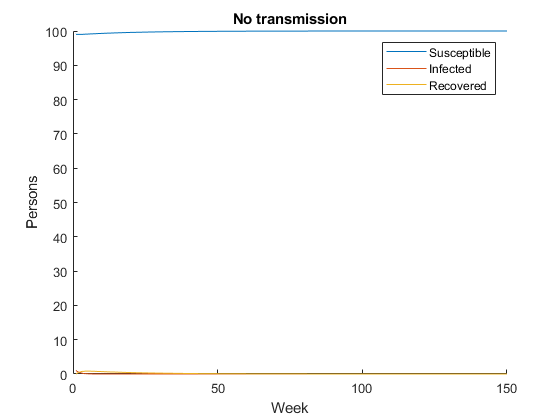

gamma = 1 / 2;
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(7); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})
title("No transmission")

Again, the model performs as expected and there are no new cases.

### Results (Controlled Model)

% Re-initialization
weeks = 100;

s_0 = 99;
i_0 = 1;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
lambda =0.75;

threshold = 10;
horizon = 10;
delay = 2;

v_threshold = threshold * (zeros(1, weeks) + 1);

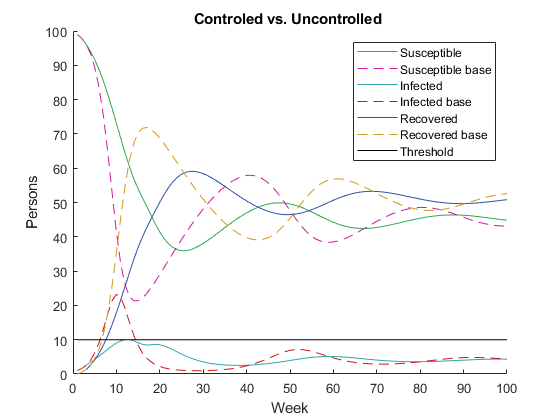

% Run the model given the parameters
[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
% Plot
figure(8); clf; hold on;
plot(W, S, 'Color', [50, 168, 82]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [209, 23, 153]/255, 'LineStyle',"--"); labelS_base = "Susceptible base";

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, I_base, 'Color', [209, 23, 23]/255, 'LineStyle',"--"); labelI_base = "Infected base";

plot(W, R, 'Color', [50, 80, 168]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [209, 153, 23]/255, 'LineStyle',"--"); labelR_base = "Recovered base";

plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
% ylim([0, threshold+5])

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base, label_threshold});
title("Controled vs. Uncontrolled ");

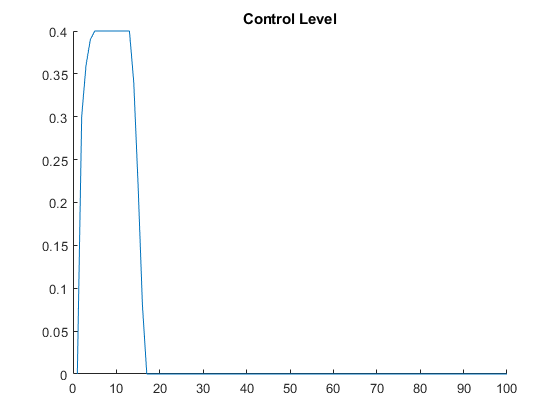

figure(9); clf; hold on;
plot(W, U); labelU = "Control";
title("Control Level");

Through running our simulations we have found that our controller is capable of controlling infection cases to within a given threshold, even when there is a multiple-week delay between control values being generated and them being actually implemented.

For both controlled and non-controlled scenarios, no matter the parameters, all values converge upon certain values. This is because there is always a circular flow between all the stocks, and thus eventually they will reach an equilibrium point where all the values settle, but not at 0. The equilibrium values are determined by the ratios between alpha, beta, and gamma, and have nothing to do with the controls. If I wanted to put even more effort into this assignment I’d derive the equilibrium values but nah.

If we set $\alpha$ to 0 and thus breaking the loop, we notice an interesting phenomenon when we drop the threshold to values under 0.5:

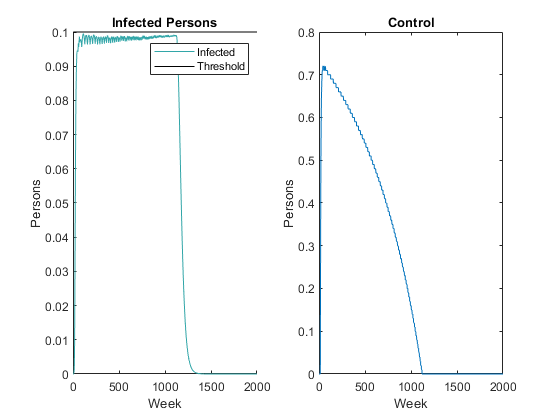

% run it for a really long time
lambda = 0.75;
alpha = 0;
weeks = 2000;
threshold = 0.1;
i_0 = 30/(6.5e6);
v_threshold = threshold * (zeros(1, weeks) + 1);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
figure(9); clf;
subplot(1,2,1); hold on;

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
title("Infected Persons");

subplot(1,2,2)
plot(W, U);
xlabel("Week")
ylabel("Persons")
title("Control");

We noticed that at low threshold values, the infected count oscillates slightly below the threshold while gradually getting closer to it, while the control values gradually drop down to 0. Around when the control values reach 0, the infected count then swiftly drops to 0. This process is slowed down for lower threshold values. Here is a plot adjusted for the amount of hospital beds in the state of Massachusetts relative to total population:

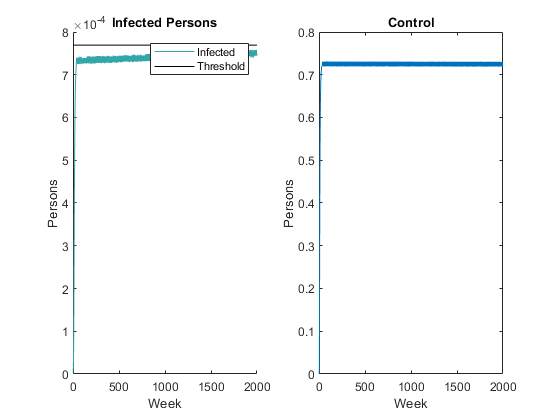

threshold = 5000/(6.5e6);
v_threshold = threshold * (zeros(1, weeks) + 1);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
figure(9); clf;
subplot(1,2,1); hold on;

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
title("Infected Persons");

subplot(1,2,2)
plot(W, U);
xlabel("Week")
ylabel("Persons")
title("Control");

Here you can see that the same trends are occurring, but over an extremely long timespan (100000 weeks). We are unsure why this is happening. Our current best guess is that since the controller only optimizes for being under the threshold, and not trying to eradicate the disease, then the case count would infinitely approach the threshold. As to why the slowness at lower thresholds, and the sudden dropoff after meeting the threshold we have a rough idea, but the explanation is very long and wordy so if you want to know just email us.

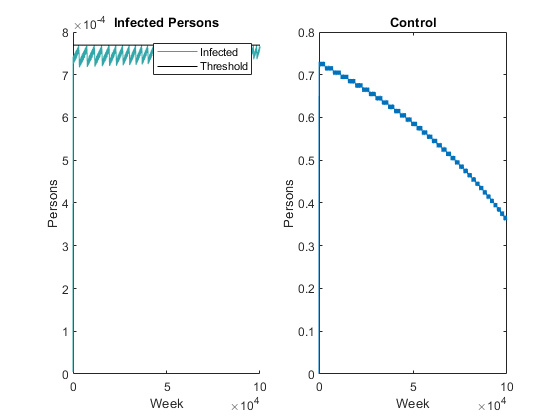

% even longer
weeks = 100000;
v_threshold = threshold * (zeros(1, weeks) + 1);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
figure(9); clf;
subplot(1,2,1); hold on;

plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
title("Infected Persons");

subplot(1,2,2)
plot(W, U);
xlabel("Week")
ylabel("Persons")
title("Control");

We also noticed that beyond a baseline, varying the prediction window length had a negligible effect on the performance of the controller.

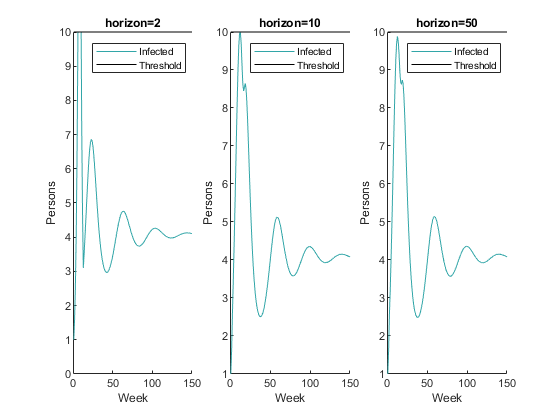

lambda = 0.75;
alpha = 0.04;
weeks = 150;
threshold = 10;
i_0 = 1;
horizon = 2;
v_threshold = threshold * (zeros(1, weeks) + 1);
figure(9); clf;

subplot(1,3,1); hold on;
horizon = 2;
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";
xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
ylim([0,10])
title("horizon=2");

subplot(1,3,2); hold on;
horizon = 10;
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";
xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
title("horizon=10");

horizon = 50;
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
subplot(1,3,3); hold on;
plot(W, I, 'Color', [50, 166, 168]/255); labelI = "Infected";
plot(W, v_threshold, 'Color', [0, 0, 0]/255); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
legend({labelI, label_threshold});
title("horizon=50");

## Interpretation

Going back to the original question: “How can the societal impacts of public health interventions be limited while keeping a pandemic within hospital capacity?” Instead of answering the question, we created a machine that can give a rough answer to the question for any pandemic and using any control method.

However, this simple controller has its obvious limitations. For starters, our MPC only seeks to keep cases under a threshold with minimal control, and does not attempt to do anything else. The controller has no concept of time - at every timestep, it only checks what the least expensive threshold-meeting control value is *at that moment*, without considering the long term implications of said control. Thus, once cases have been kept under the threshold, the controller is satisfied with merely indefinitely keeping the cases under the threshold and sees no point in pushing further, at the expense of an exorbitant long term cost that could’ve been avoided had the disease been eradicated in the beginning. In short, this model is an excellent predictor of how the United States would handle Covid-19.

This can be alleviated through two ways. The first way is through a simple integral term on the total infected case count. The control term could have an extra term added on: $\textrm{ki}\int_0^t I\;\textrm{dt}$. This adds a way for the controller to be cognisant of the past infected case count, and as that integral grows the control would increase as well, bringing the total infected-over-time down. The limitation of this method is that it only looks in the past, and does not consider the cost of the predicted future controls. The other way would be through a proper MPC implementation. Specifically, we lack the cost function of an MPC where we can add an extra cost term for the “cost” of the control we are using. The proper MPC implementation would include the cost function as part of its predicting model, and thus would factor in the cost of controls as it generates control terms based on predictions made with the model.

Another limitation of the simulation is that the “real world” that we are simulating on is too ideal and similar to the prediction model. Thus, the model is able to nearly perfectly predict what is going to happen next. Thus, we are unable to truly test the robustness of our controller. In the future, one could use a more complex world model than the prediction model to simulate the real world being more complex than any mathematical model one might develop. One such model to use would be the SIRASDC model listed here (https://arxiv.org/pdf/2005.10797.pdf). 

Our model also only currently models a singular control through $\lambda u$. While this control can be a combination of multiple sources, you cannot model the effects of each source individually. More terms could be added to simulate different ways of controlling the system.